Given the attached dataset, identify and validate a NFIR model of the processes.

------------------------------------------------------------------------------------------------------

**1. Process the data**

Load the dataset

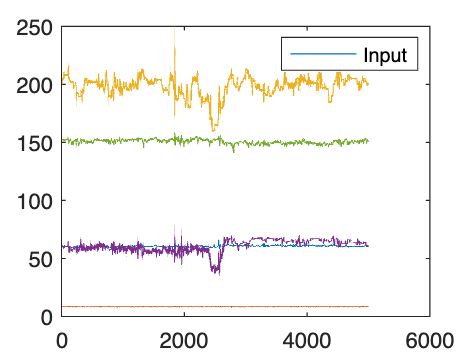

input_data = load('ingresso_fir.csv'); 
output_data = load('uscita_fir.csv'); 
plot(input_data);
legend({'Input'})

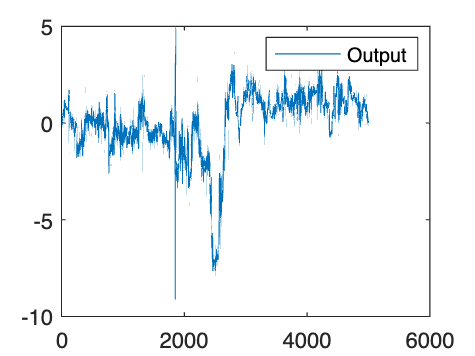


plot(output_data)
legend({'Output'})

We have the time series data.

**3 sigma-rule** is a simple and widely used heuristic for outlier detection. Basically any observations that fall outside of three standard deviations from the mean is considered an outlier.

sigma_output = (output_data - mean(output_data))/std(output_data);
sigma_input = (input_data -  mean(input_data))/std(input_data);
% std(): standard deviation
outliers_output = find(abs(sigma_output) >= 3)

outliers_output =         1852
        2441
        2442
        2443
        2444
        2445
        2446
        2447
        2448
        2449


outliers_input = find(abs(sigma_input) >= 3)

outliers_input =         1845
        2433
        2435
        2436
        2437
        2438
        2439
        2440
        2441
        2442


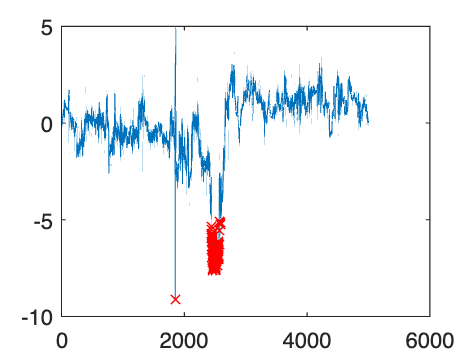

plot(output_data)
hold on
plot(outliers_output, output_data(outliers_output), 'rx')
hold off

**Z-score normalization**

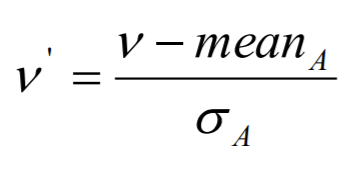               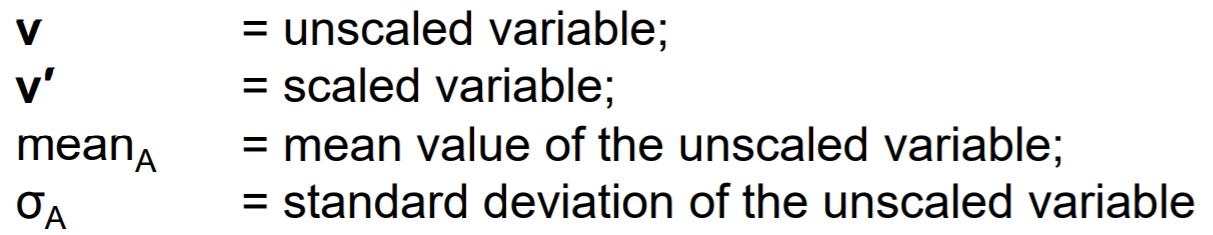

 **σ - standard deviation: **how far each value is from the mean

Normalize the data to get the same unit for all

input = zscore(input_data);
output = zscore(output_data);

io_normalization = zscore([input_data, output_data])

io_normalization =    -0.0164   -0.2733    0.1381    0.0495    0.8484    0.0002
   -0.0702   -0.4488    0.2313    0.0493    0.8371    0.0002
   -0.1241   -0.1776    0.2495    0.0491    0.9274    0.0002
   -0.1779   -0.5951    0.2506    0.0491    0.9048    0.0002
   -0.2318   -0.5472    0.4257    0.0489    0.8822    0.0002
   -0.2856    0.1202    0.4291    0.0487    0.8596    0.0002
   -0.3394   -0.0925    0.4575    0.0485    0.8314    0.0002
   -0.3933   -0.7546    0.4313    0.0483    0.8709    0.0002
   -0.4486   -0.5233    0.4529    0.0481    0.9387    0.0002
   -0.5024   -0.7812    0.4098    0.0480    1.0008    0.0002


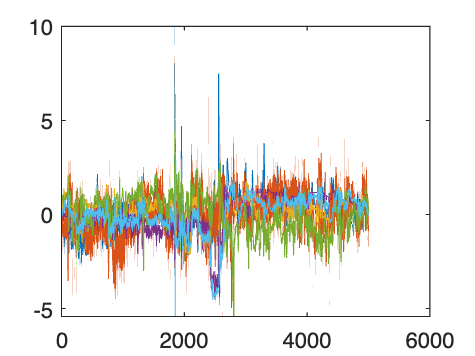

plot(io_normalization)


% The values used to accomplish the normalization
% must be computed on the whole data set and
% must not be changed in any further data manipulation

**Data partitioning**

The whole data set (coming from selection from the historical data base or from ad-hoc experiments) should be partitioned as:

- Identification data: to identify candidate models

- Test data: to select the suitable model 

- Validation data: to validate the model 

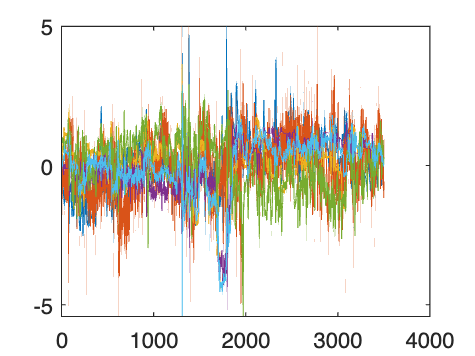

% Cross validation: a model assessment technique used to 
% evaluate a machine learning algorithm's performance in making 
% predictions on new datasets that it has not been trained on

% cvpartition: random result each time
% identification: 70%, validation: 30%
% Holdout: separates the data into exactly two subsets 
% of specified ratio for training and validation

% Separate input to identification and validation data
cv = cvpartition(size(input,1),'Holdout',0.3);
mid = cv.test;
input_identification = input(~mid,:);
input_validation  = input(mid,:);

% Separate output to identification and validation data
cv = cvpartition(size(output,1),'Holdout',0.3);
mid = cv.test;
output_identification = output(~mid,:);
output_validation  = output(mid,:);

plot([input_identification output_identification])

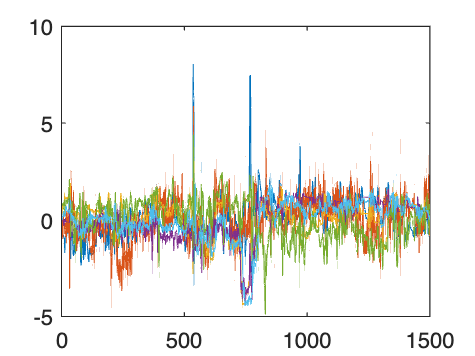

plot([input_validation output_validation])

**Cross correlation **

Check the correlation between the identification and validation data sets.

disp('Input-Output identification')

Input-Output identification


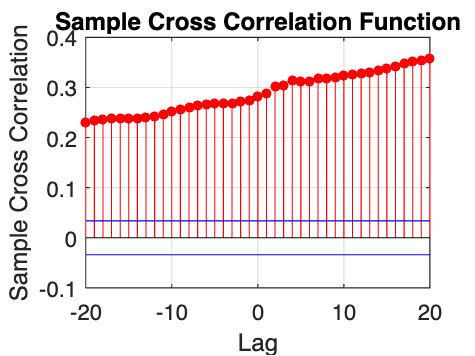

crosscorr(input_identification(:,1),output_identification)

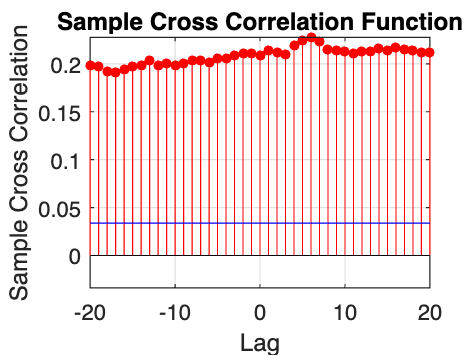

crosscorr(input_identification(:,2),output_identification)

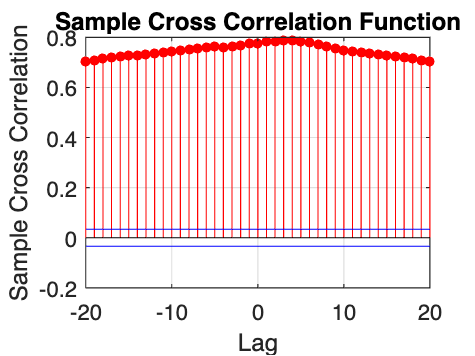

crosscorr(input_identification(:,3),output_identification)

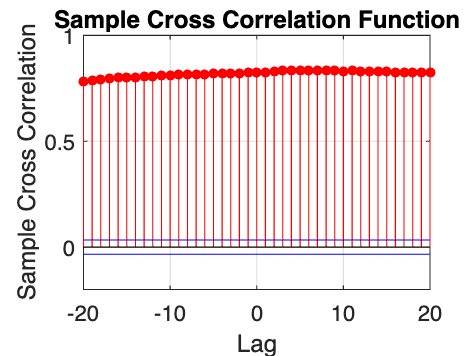

crosscorr(input_identification(:,4),output_identification)



disp('Input-Output validation')

Input-Output validation


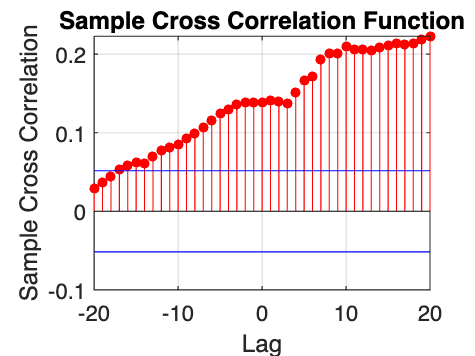

crosscorr(input_validation(:,1),output_validation)

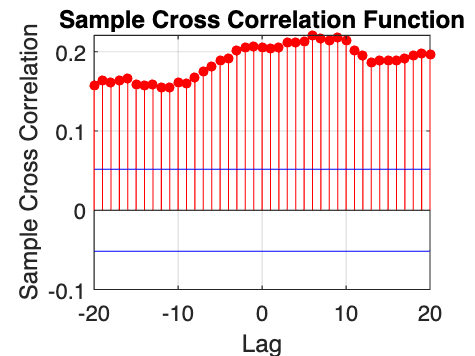

crosscorr(input_validation(:,2),output_validation)

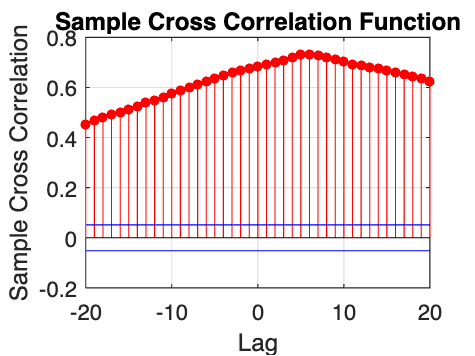

crosscorr(input_validation(:,3),output_validation)

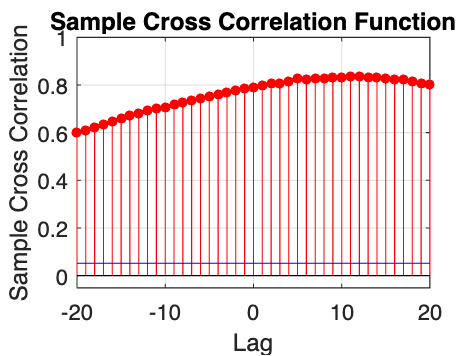

crosscorr(input_validation(:,4),output_validation)

There is no relevant correlation between the identification and validation, so there's no model for this. 

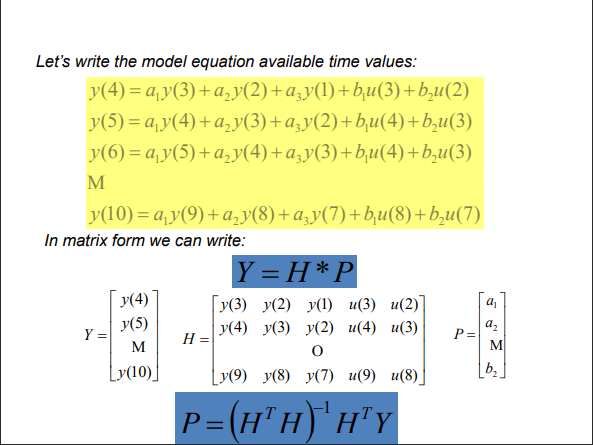

**2. FIR**

FIR**: **Finite Impulse Response

The FIR model structure is given by the following equation:

disp('---------------------------')

---------------------------


disp('FIR')

FIR


disp('2nd order FIR model')

2nd order FIR model


input_identification = input_identification(:,4)

input_identification =     0.0495
    0.0491
    0.0491
    0.0489
    0.0483
    0.0481
    0.0480
    0.0480
    0.0478
    0.0476


% H_fir: the matrix that from input data, we predict the output
H_fir = [input_identification(2:3499) input_identification(1:3498)];
estimated_parameter_fir = inv(H_fir'*H_fir)*H_fir'*output_identification(3:3500);
disp(estimated_parameter_fir)

    0.3246
    0.5144



estimated_outputs_fir = H_fir * estimated_parameter_fir % predicted value

estimated_outputs_fir =     0.0414
    0.0412
    0.0411
    0.0408
    0.0405
    0.0403
    0.0402
    0.0402
    0.0400
    0.0399


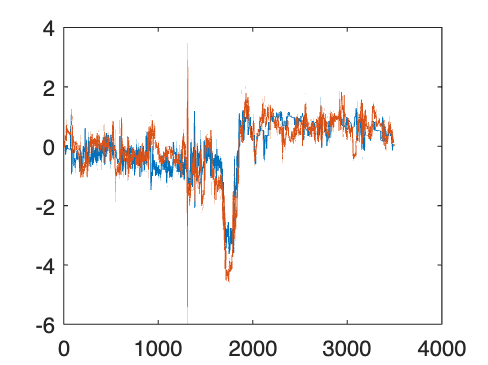

plot([estimated_outputs_fir output_identification(3:3500)])

disp('correlation between estimated and identification output')

correlation between estimated and identification output


corr(estimated_outputs_fir,output_identification(3:3500));

Analyze the output identification data:

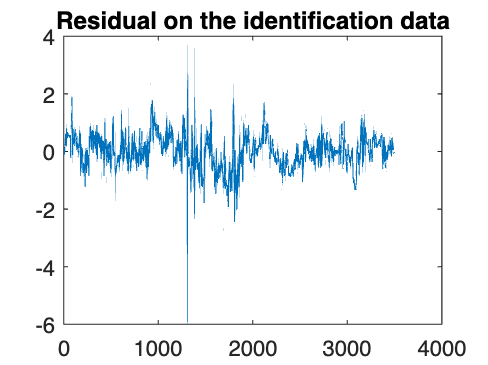

% Residuals are the differences
% between observed and predicted values of data
residual = output_identification(3:3500) - estimated_outputs_fir;
plot(residual);
title("Residual on the identification data");

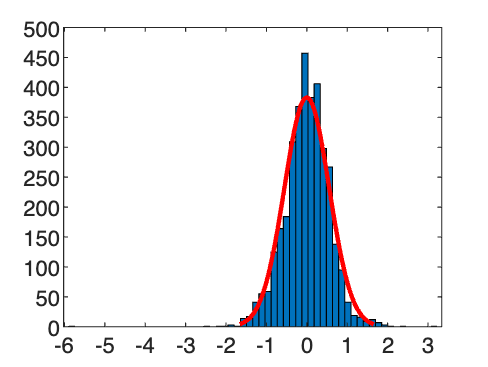

histfit(residual);

% mean squared error
mse = (immse(output_identification(3:3500), estimated_outputs_fir));
disp("Mean squared error: " + mse);

Mean squared error: 0.30624


Estimated validation input/output data:

input_validation = input_validation(:, 4)

input_validation =     0.0493
    0.0487
    0.0485
    0.0466
    0.0465
    0.0461
   -0.1366
   -0.1727
   -0.2790
   -0.2954


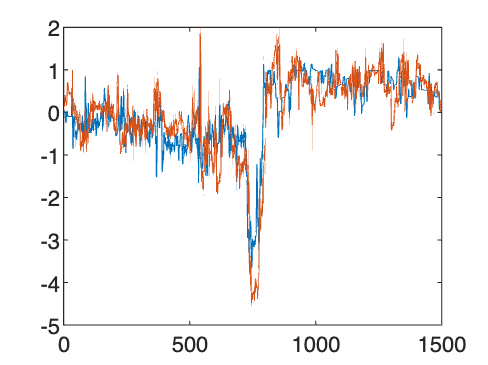

Hval_fir=[input_validation(2:1499) input_validation(1:1498)];
estimated_outputs_val = Hval_fir * estimated_parameter_fir;
plot([estimated_outputs_val output_validation(3:1500)])

disp('correlation between estimated and validation output')

correlation between estimated and validation output


corr(estimated_outputs_val,output_validation(3:1500))

ans = 0.8102

Analyze the output validation data:

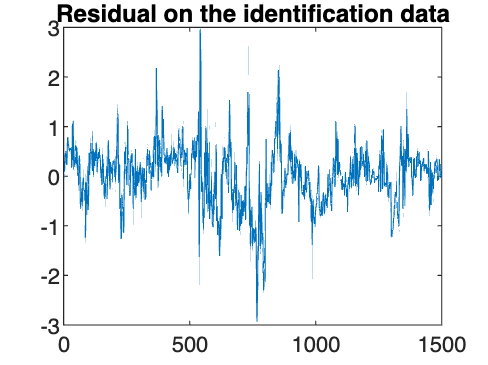

residual = output_validation(3:1500) - estimated_outputs_val;
plot(residual);
title("Residual on the identification data");

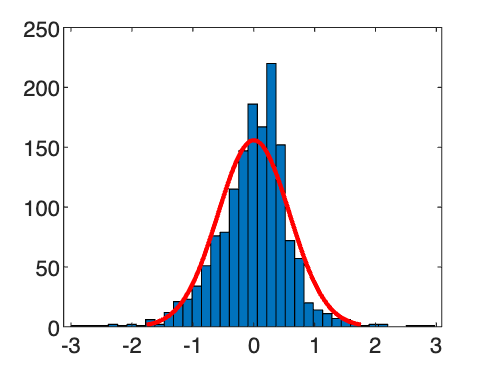

histfit(residual);

% mean squared error
mse = (immse(output_validation(3:1500), estimated_outputs_val));
disp("Mean squared error: " + mse);

Mean squared error: 0.34409
